% % Find eyes 
% C1 = imread('../db/DB0/db0_1.jpg');
% imshow(C1)
% 
% SE = strel('disk',3);
% IM2 = imopen(C1, SE);
% IM3 = imclose(IM2, SE);
% %disp(SE.Neighborhood)
% imshow(IM3)
% 
% %10
% SE2 = strel('line',6,0);
% IM4 = imopen(IM3, SE2);
% IM5 = imclose(IM4, SE2);
% imshow(IM5)


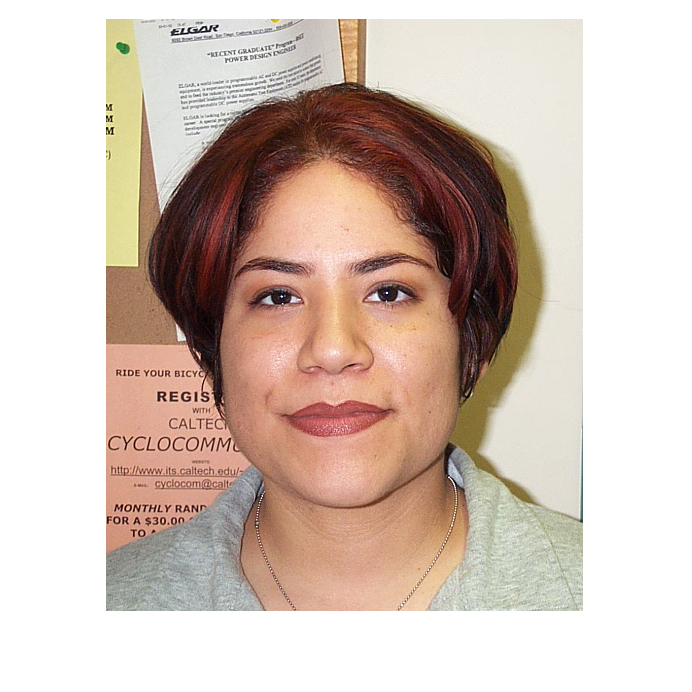

C1 = imread('../db/DB0/db0_1.jpg');
imshow(C1)

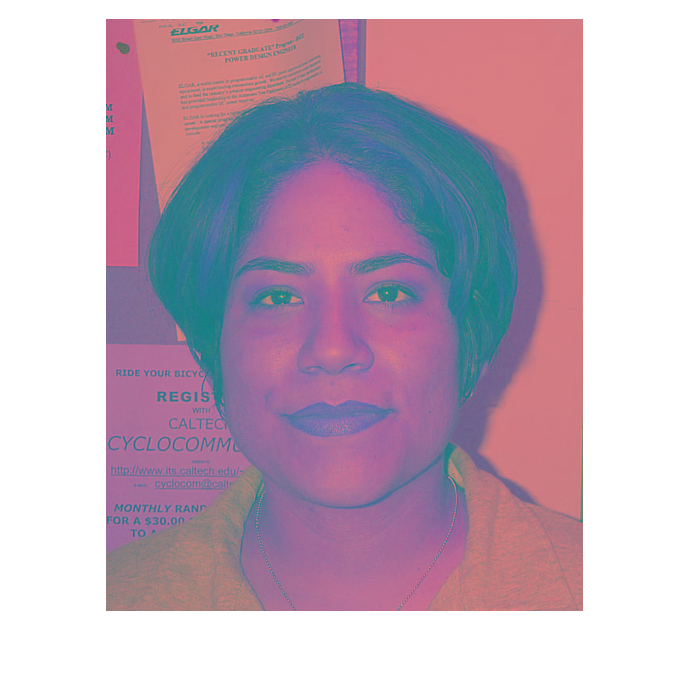

C2 = rgb2ycbcr(C1);
imshow(C2)

C3 = im2double(C2);
imshow(C3)

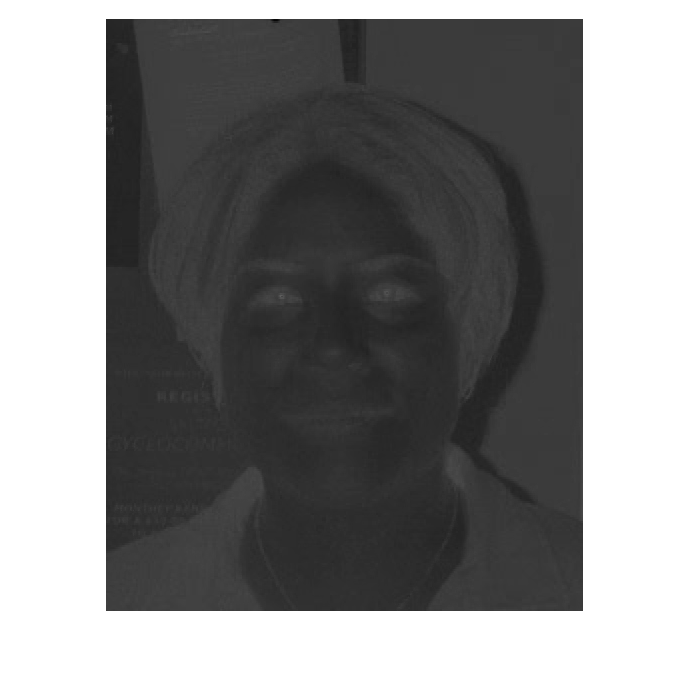


y=C3(:,:,1);
cb=C3(:,:,2);
cr=C3(:,:,3);
ccb=cb.^2;
imshow(ccb)

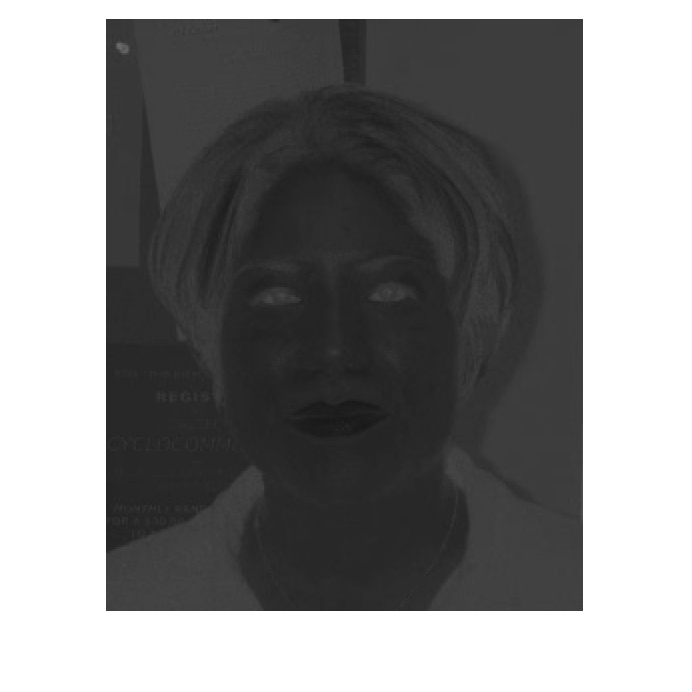


ccr=(1-cr).^2;
imshow(ccr)

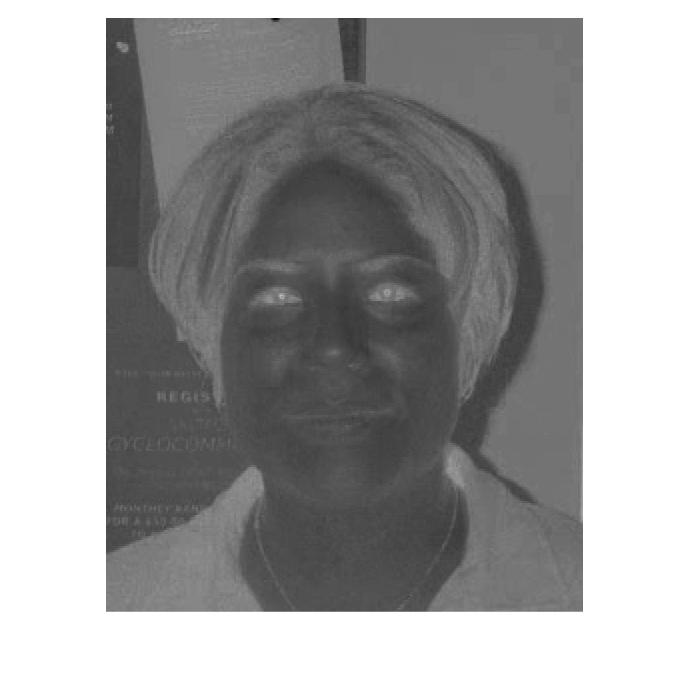


cbcr=ccb./cr;
imshow(cbcr)

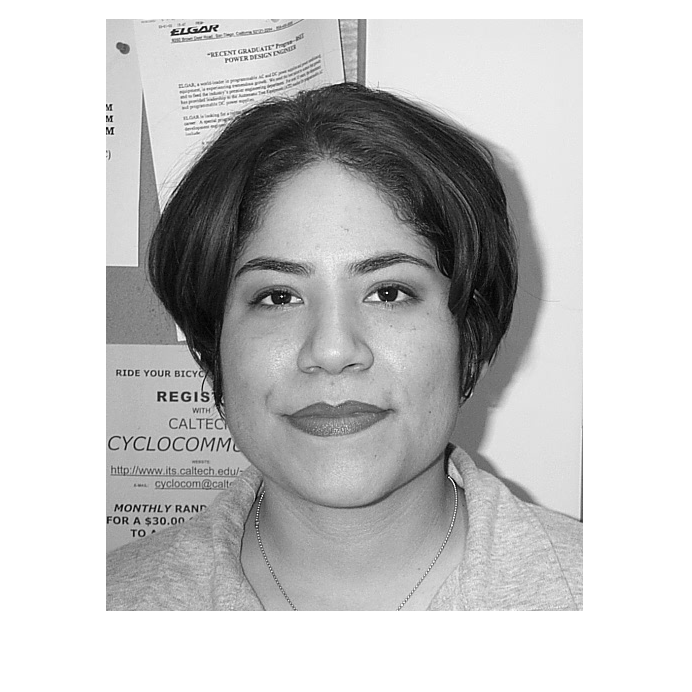


C4=rgb2gray(C1);
imshow(C4)

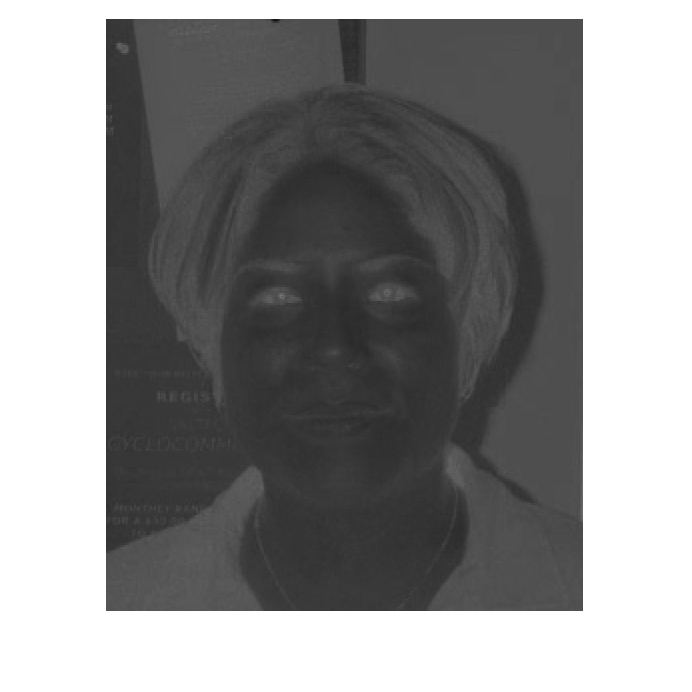


%EyemapC
g=1./3;
l=g*ccb;
m=g*ccr;
n=g*cbcr;
C5=l+m+n;
imshow(C5)

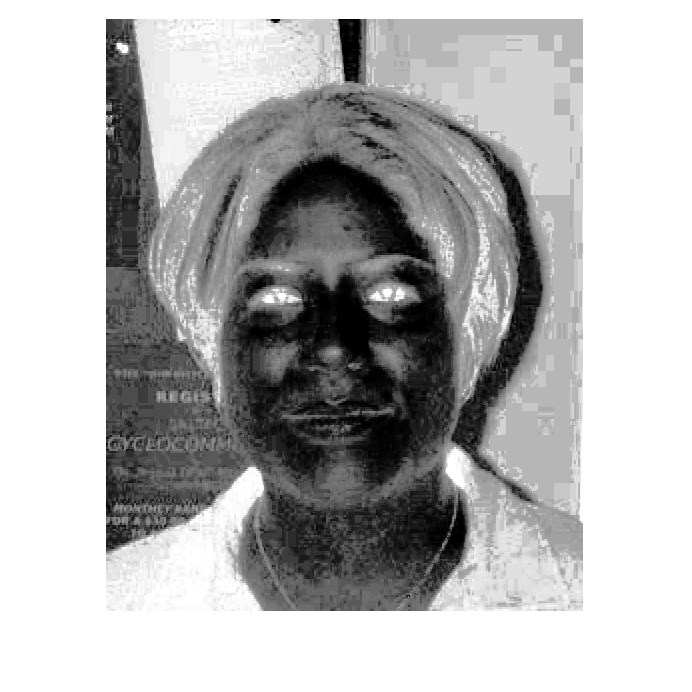


%Histogram equalization
C6=histeq(C5);
imshow(C6)


%EyemapL
SE=strel('disk',4);
o=imdilate(C4,SE);
p=1+imerode(C4,SE);
C7=o./p;
C8 = im2double(C7)

C8 =     0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0039    0.0039    0.0039    0.0039
    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0078    0.0039    0.0039    0.0039    

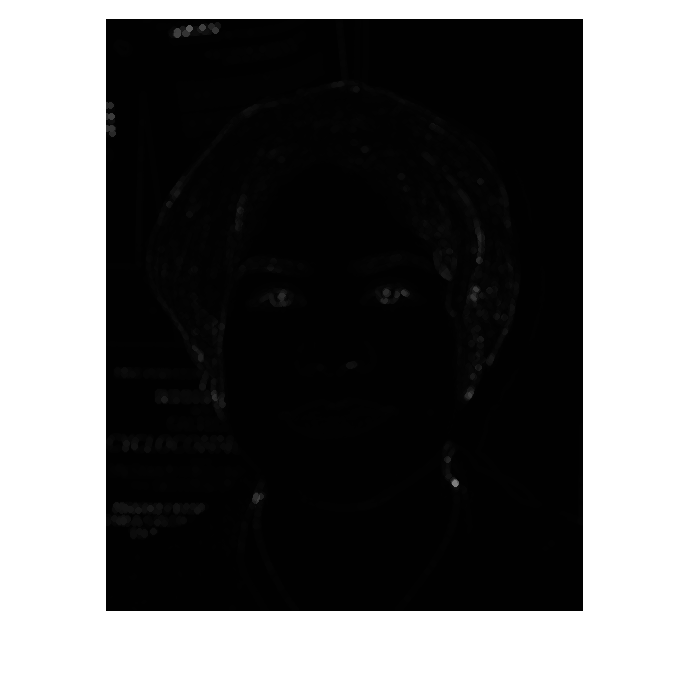

imshow(C8)

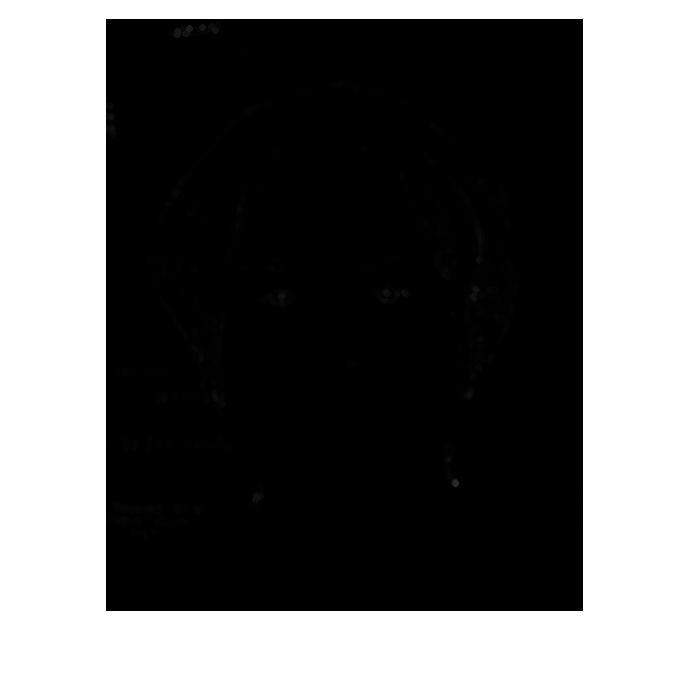


result = C5 .*C8;
imshow(result)